# Random-Target Practical Time Reversal

This Live Script builds a random-target 2-D TMz test case, runs total and incident FDTD simulations, subtracts scattered receiver traces, and backpropagates them with practical time reversal. The practical TR input is $ d_m^{\\mathrm{scat}}(t)=d_m^{\\mathrm{tot}}(t)-d_m^{\\mathrm{inc}}(t) $. The TR solver injects $ d_m^{\\mathrm{TR}}[n]=d_m^{\\mathrm{scat}}[N_t-n+1] $ from the antenna locations.

## Setup And Controls

Edit these controls directly for experiments. A blank`randomSeed` gives a new random target set on each run.

repoRoot = pwd;
scriptFile = mfilename('fullpath');
try
    activeFile = matlab.desktop.editor.getActiveFilename;
catch
    activeFile = '';
end
if ~isempty(activeFile)
    scriptFile = activeFile;
end
candidateRoots = {pwd};
if ~isempty(scriptFile)
    scriptFolder = fileparts(scriptFile);
    candidateRoots = [candidateRoots, {scriptFolder, fileparts(scriptFolder)}];
end
for rootIdx = 1:numel(candidateRoots)
    if exist(fullfile(candidateRoots{rootIdx}, 'README.md'), 'file') == 2
        repoRoot = candidateRoots{rootIdx};
        break
    end
end
workspaceRoot = fileparts(fileparts(fileparts(repoRoot)));
addpath(fullfile(workspaceRoot, 'buildLib'));
addpath(fullfile(repoRoot, 'lib'));
addpath(fullfile(workspaceRoot, 'forward_solver', 'mex'));
if exist('fdtd_mex', 'file') ~= 3
    error('time_reversal_random_practical:MissingMex', ...
        'Compile forward_solver/mex/fdtd_mex before running this workflow.');
end
requiredFunctions = {'buildPlanarAntennaIdx', 'generateRandomTargetSpecs', ...
    'computeScatteredReceivers', 'prepareTracesForTR', ...
    'plotTrComparison', 'plotTraceDiagnostics'};
for functionIdx = 1:numel(requiredFunctions)
    if exist(requiredFunctions{functionIdx}, 'file') ~= 2
        error('time_reversal_random_practical:MissingFunction', '%s must be on the MATLAB path.', requiredFunctions{functionIdx});
    end
end
randomSeed = [];
target_opts = struct();
target_opts.numTargetsRange = [1 3];
target_opts.allowedShapes = ["circle" "rectangle" "triangle"];
target_opts.radiusRange = [10 28];
target_opts.sideRange = [18 50];
target_opts.epsrRange = [2.5 6.0];
target_opts.condRange = [0.02 0.15];
target_opts.maxAttempts = 800;
target_opts.allowOverlap = false;
pulse_width = 20e-12;
pulse_delay_factor = 4;
source_amplitude = 10;
control_default = @(value) value;
remove_tx_channel = control_default(false);
apply_temporal_window = control_default(true);
normalize_receiver_traces = control_default(false);
store_forward_histories = control_default(false);
store_tr_history = true;% control_default(false);
tr_history_stride = 5;
show_comparison_figure = control_default(true);
show_receiver_trace_diagnostics = control_default(true);
show_tr_animation = control_default(false);
tr_animation_pause = 0.01;
use_incident_medium_for_tr = control_default(true);
use_absorbing_pml_for_tr = true;
temporal_window_tau = pulse_width;
if ~isempty(randomSeed)
    rng(randomSeed);
end
clear control_default

## Build Grid, PML, And Antennas

The planar array defines the domain of interest used later as the focus ROI: $ \\Omega_{\\mathrm{ROI}}=\\Omega_{\\mathrm{DOI}} $.

%% 0. Initialize cfg
cfg = struct();

%% 1. Basic grid parameters
cfg.c0 = 3e8;
cfg.mu0 = 4*pi*1e-7;
cfg.eps0 = 8.854e-12;
cfg.Nx = 259;
cfg.Ny = 259;
cfg.dx = 1e-3;
cfg.dy = 1e-3;
cfg.max_eps_r = max([1.0, target_opts.epsrRange]);
cfg.dt = 0.25 * sqrt(cfg.max_eps_r) / ...
    (cfg.c0 * sqrt(1/cfg.dx^2 + 1/cfg.dy^2));
cfg.Nt = 800;
cfg.sizeZ = 1;
cfg.snapshotStart = 0;
cfg.snapshotStride = 0;
if store_forward_histories
    cfg.snapshotStride = 1;
end
cfg.returnEz = logical(store_forward_histories);
cfg.returnHx = false;
cfg.returnHy = false;
cfg.returnRxSignals = true;

%% 2. Grid
cfg.grid = struct();
cfg.grid.background = struct( ...
    'epsr', 1.0, ...
    'murx', 1.0, ...
    'mury', 1.0, ...
    'cond_e', 0.0, ...
    'cond_m', 0.0);
cfg.grid = fdtdmat.createGrid([cfg.Nx cfg.Ny], [cfg.dx cfg.dy], ...
    cfg.grid.background, [0 0]);

%% 3. PML
cfg.pml = fdtdpml.build_rectangularPML(cfg.grid, 20, 3, ...
    -(3 + 1) * log(1e-60) / ...
    (2 * sqrt(cfg.mu0/cfg.eps0) * 20 * cfg.dx), 1.0);
cfg.pml.thickness = 20;
cfg.pml.m = 3;
cfg.pml.R = 1e-60;
cfg.pml.eta0 = sqrt(cfg.mu0/cfg.eps0);
cfg.pml.d = cfg.pml.thickness * cfg.dx;
cfg.pml.sigma_max = -(cfg.pml.m + 1) * log(cfg.pml.R) / ...
    (2 * cfg.pml.eta0 * cfg.pml.d);
cfg.pml.sigma_e = max(cfg.pml.condx, cfg.pml.condy);
cfg.pml.type = 'cpml';
cfg.pml.enabled = true;
cfg.pml.ax = 1;
cfg.pml.ay = 1;
cfg.pml.az = 1;

%% 5. Antennas
cfg.antennas.numAntennas = 23;
cfg.antennas.pmlPadding = 5;
cfg.antennas.focusPadding = 10;
cfg.antennas.orientation = 'top';
cfg = buildPlanarAntennaIdx(cfg);
num_antennas = cfg.antennas.numAntennas;
tx_antenna = ceil(num_antennas/2);
cfg.antennas.txAntennas = tx_antenna; % Select the initial TR transmitting antenna.

## Generate And Apply Random Targets

Target generation only creates readable specs. The material application loop remains explicit so each geometry and property assignment is visible.

%% 4. Targets

       Name         EpsR      CondE  
    ___________    ______    ________

    "rectangle"    3.0992     0.11179
    "triangle"     3.1541    0.083669
    "rectangle"    2.9165    0.084787



cfg.targets = generateRandomTargetSpecs(cfg.grid, cfg.antennas.doiMask, target_opts);
for targetIdx = 1:numel(cfg.targets)
    cfg.grid = fdtdmat.applyRegion(cfg.grid, cfg.targets(targetIdx), ...
        cfg.targets(targetIdx).material);
end
target_name = string({cfg.targets.name}).';
target_epsr = arrayfun(@(target) target.material.epsr, cfg.targets).';
target_cond_e = arrayfun(@(target) target.material.cond_e, cfg.targets).';
target_table = table(target_name, target_epsr, target_cond_e, ...
    'VariableNames', {'Name', 'EpsR', 'CondE'});
disp(target_table);

## Build Source And Config

The source is a differentiated Gaussian pulse, normalized to the requested amplitude.

%% 6. Source
source_time = (0:cfg.Nt-1) .* cfg.dt;
t_delay = pulse_delay_factor * pulse_width;
source_normalization = max(abs(-((source_time - t_delay) ./ pulse_width.^2) .* ...
    exp(-0.5 .* ((source_time - t_delay) ./ pulse_width).^2)));
cfg.source.location = cfg.antennas.pos;
cfg.source.func = @(physicalTime) source_amplitude .* ...
    (-((physicalTime - t_delay) ./ pulse_width.^2) .* ...
    exp(-0.5 .* ((physicalTime - t_delay) ./ pulse_width).^2)) ./ source_normalization;

cfg.opts = struct();
cfg.opts.storeFieldHistory = store_forward_histories; % Retain optional forward Ez histories.

## Forward Scattered Receiver Data

Two forward simulations are run with the same antenna/source setup. Only receiver traces are subtracted; full field histories are optional diagnostics.

incident_cfg = fdtdmat.setBackgroundDefault(cfg, cfg.grid.background);
if isfield(incident_cfg, 'targets')
    incident_cfg.targets = struct([]);
end
source_samples = zeros(num_antennas, cfg.Nt);
source_samples(tx_antenna, :) = cfg.source.func(source_time);
cfg.source.samples = source_samples;
incident_cfg.source.samples = source_samples;
fprintf('Running total-field MEX propagation...\n');
result_tot = fdtd_mex(cfg);
fprintf('Running incident-field MEX propagation...\n');
result_inc = fdtd_mex(incident_cfg);
if ~isfield(result_tot, 'rx_signals') || ~isfield(result_inc, 'rx_signals')
    error('time_reversal_random_practical:MissingReceiverSignals', ...
        'Forward MEX runs must return result.rx_signals.');

Transmitting from antenna 12/23...


end

Transmitting from antenna 12/23...


rx_scat = computeScatteredReceivers(result_tot, result_inc);
if store_forward_histories
    E_tot = result_tot.Ez;
    E_inc = result_inc.Ez;
    E_scat = E_tot - E_inc;
end

## Prepare Time-Reversal Traces

Temporal windowing uses $ g_m(t)=d_m^{\\mathrm{scat}}(t)\\exp[-((t-t_{p,m})/\\tau)^2]$, where $ t_{p,m} $ is the peak time of receiver $m$.

trace_opts = struct();
trace_opts.removeTxChannel = remove_tx_channel;
trace_opts.txAntenna = tx_antenna;
trace_opts.applyTemporalWindow = apply_temporal_window;
trace_opts.temporalWindowTau = temporal_window_tau;
trace_opts.normalizeTraces = normalize_receiver_traces;
[tr_data_rev, traceInfo] = prepareTracesForTR(rx_scat, cfg.dt, trace_opts);
tr_data = traceInfo.windowed;
temporal_window = traceInfo.temporalWindow;
temporal_window_peak_index = traceInfo.peakIndex;
temporal_window_peak_time = traceInfo.peakTime;

## Practical TR Computation

The TR run starts from zero fields and injects the reversed scattered receiver traces. The Mag image selects the frame with largest ROI magnitude; the Entropy image minimizes $ R(t)=\\frac{(\\sum_{\\Omega_{ROI}}|E|^2)^2}{\\sum_{\\Omega_{ROI}}|E|^4} $.

if use_incident_medium_for_tr
    tr_cfg = incident_cfg;
else
    tr_cfg = cfg;
end
fprintf('Running time-reversal MEX propagation...\n');
tr_cfg.source.samples = tr_data_rev;
tr_cfg.snapshotStart = 0;
tr_cfg.snapshotStride = 1;
tr_cfg.returnEz = true;
tr_cfg.returnHx = false;

Running TR propagation for 800 steps in receiverInjection mode...


tr_cfg.returnHy = false;
tr_cfg.returnRxSignals = true;
tr_mex_result = fdtd_mex(tr_cfg, true);
tr_result = analyzeTimeReversal(tr_mex_result, cfg.antennas.doiMask, ...
    store_tr_history, tr_history_stride);
trInfo = struct();
trInfo.focusMask = cfg.antennas.doiMask;

    PeakImageValue    FocusMagPeakDOI    FocusMagStep    FocusEntropyR    FocusEntropyStep    DOIPixels    RemovedTxChannel    TemporalWindow    WindowTauPs    NormalizedTraces    UsedIncidentMedium    AbsorbingPML    PMLPixels    LossMode
    ______________    _______________    ____________    _____________    ________________    _________    ________________    ______________    ___________    ________________    __________________    ____________    _________    ________

      0.0081463          0.0025212         

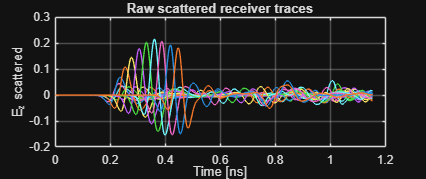

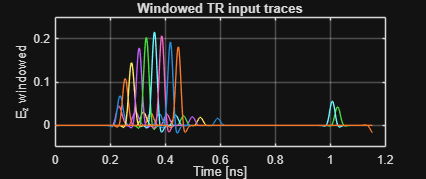

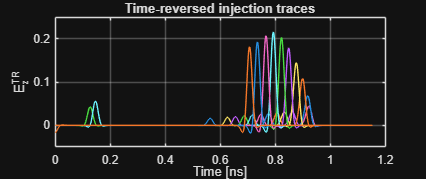

trInfo.pmlPixels = nnz((cfg.pml.condx > 0) | (cfg.pml.condy > 0));
trInfo.useIncidentMedium = use_incident_medium_for_tr;
trInfo.useAbsorbingPml = true;
trInfo.lossMode = "native";
trInfo.historyStride = tr_history_stride;
image_max = tr_result.image_max;

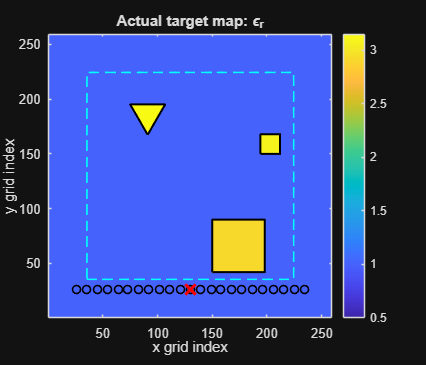

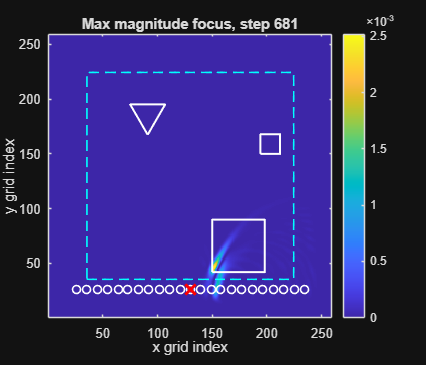

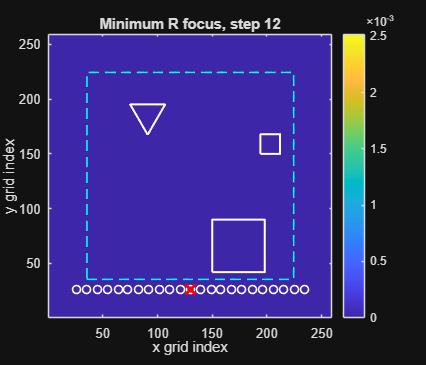

ans =   1×3 Figure array:

    Figure    Figure    Figure


tr_focus_mag_image = tr_result.focus_mag_image;

tr_focus_entropy_image = tr_result.focus_entropy_image;
tr_rx_signals = tr_result.rx_signals;
tr_summary = table(max(image_max(:)), tr_result.focus_mag_peak_value, tr_result.focus_mag_step, tr_result.focus_entropy_value, tr_result.focus_entropy_step, nnz(trInfo.focusMask), remove_tx_channel, apply_temporal_window, traceInfo.temporalWindowTau * 1e12, normalize_receiver_traces, use_incident_medium_for_tr, use_absorbing_pml_for_tr, trInfo.pmlPixels, string(tr_result.loss_mode), ...
    'VariableNames', {'PeakImageValue', 'FocusMagPeakDOI', 'FocusMagStep', 'FocusEntropyR', 'FocusEntropyStep', 'DOIPixels', 'RemovedTxChannel', 'TemporalWindow', 'WindowTauPs', 'NormalizedTraces', 'UsedIncidentMedium', 'AbsorbingPML', 'PMLPixels', 'LossMode'});
disp(tr_summary);

## Visualizations

The comparison figure shows the actual permittivity map, the max-magnitude focusing frame, and the minimum-$R(t)$ focusing frame.

if show_receiver_trace_diagnostics
    trace_fig = plotTraceDiagnostics(traceInfo, cfg.dt);
end
plotTrComparison(cfg, tr_result)

## Optional TR Animation

Enable`store_tr_history` and`show_tr_animation` to play the stored TR field history. This is separate from receiver trace recording.

if show_tr_animation
    if isfield(tr_result, 'Ez_reversed_all') && ~isempty(tr_result.Ez_reversed_all)
        Ez_reversed_all = tr_result.Ez_reversed_all;
        tr_history_steps = tr_result.history_steps;
        movie_clim = max(abs(Ez_reversed_all(:)));
        if movie_clim == 0 || ~isfinite(movie_clim)
            movie_clim = 1;
        end
        animation_fig = figure('Name', 'TR E_z playback', 'Position', [220 160 760 650]);
        for movie_idx = 1:size(Ez_reversed_all, 3)
            figure(animation_fig)
            clf(animation_fig)
            imagesc(Ez_reversed_all(:, :, movie_idx)')
            axis equal tight
            set(gca, 'YDir', 'normal')
            colorbar
            clim([-movie_clim movie_clim])
            title(sprintf('TR E_z playback frame %d/%d, step %d', movie_idx, size(Ez_reversed_all, 3), tr_history_steps(movie_idx)))
            xlabel('x grid index')
            ylabel('y grid index')
            drawnow
            pause(tr_animation_pause)
        end
    else
        warning('time_reversal_random_practical:MissingTrMovie', 'Set store_tr_history = true and rerun to create tr_result.Ez_reversed_all.');
    end
end

function result = analyzeTimeReversal(mexResult, focusMask, storeHistory, historyStride)
%analyzeTimeReversal Compute focusing products from the complete MEX Ez history.

EzAll = mexResult.Ez;
numSteps = size(EzAll, 3);
imageMax = zeros(size(focusMask));
focusMagImage = zeros(size(focusMask));
focusMagEz = zeros(size(focusMask));
focusMagPeakValue = -inf;
focusMagStep = 1;
focusEntropyImage = zeros(size(focusMask));
focusEntropyEz = zeros(size(focusMask));
focusEntropyValue = inf;
focusEntropyStep = 1;
entropyAbsTol = 1e-15;
entropyRelTol = 1e-12;

for step = 1:numSteps
    EzFrame = EzAll(:, :, step);
    framePower = abs(EzFrame).^2;
    imageMax = max(imageMax, framePower);
    framePeakValue = max(framePower(focusMask));
    if framePeakValue > focusMagPeakValue
        focusMagPeakValue = framePeakValue;
        focusMagStep = step;
        focusMagEz = EzFrame;
        focusMagImage = framePower;
    end
    roiAmplitude = abs(EzFrame(focusMask));
    roiPeakAmplitude = max(roiAmplitude);
    if roiPeakAmplitude > entropyAbsTol
        entropyCutoff = max(entropyAbsTol, entropyRelTol .* roiPeakAmplitude);
        validAmplitude = roiAmplitude(roiAmplitude >= entropyCutoff);
        normalizedPower = (validAmplitude ./ roiPeakAmplitude).^2;
        entropyWeights = normalizedPower ./ sum(normalizedPower);
        frameEntropyValue = 1 ./ sum(entropyWeights.^2);
    else
        frameEntropyValue = inf;
    end
    if frameEntropyValue < focusEntropyValue
        focusEntropyValue = frameEntropyValue;
        focusEntropyStep = step;
        focusEntropyEz = EzFrame;
        focusEntropyImage = framePower;
    end
end

result = struct();
result.Ez_reversed = EzAll(:, :, end);
result.image_max = imageMax;
result.tr_mode = "receiverInjection";
result.loss_mode = "native";
result.num_steps = numSteps;
result.rx_signals = mexResult.rx_signals;
result.focus_mag_image = focusMagImage;
result.focus_mag_Ez = focusMagEz;
result.focus_mag_step = focusMagStep;
result.focus_mag_peak_value = focusMagPeakValue;
result.focus_entropy_image = focusEntropyImage;
result.focus_entropy_Ez = focusEntropyEz;
result.focus_entropy_step = focusEntropyStep;
result.focus_entropy_value = focusEntropyValue;
result.focus_mask = focusMask;
if storeHistory
    historySteps = unique([1:historyStride:numSteps, numSteps]);
    result.Ez_reversed_all = EzAll(:, :, historySteps);
    result.history_steps = historySteps;
    result.history_stride = historyStride;
    result.store_magnetic_history = false;
end
end